digitDatasetPath = '/Users/wujunting/Documents/MATLAB/牙齒照片/已切完的病徵照片';
mainPath = '/Users/wujunting/Documents/MATLAB/牙齒照片/所有圖';
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

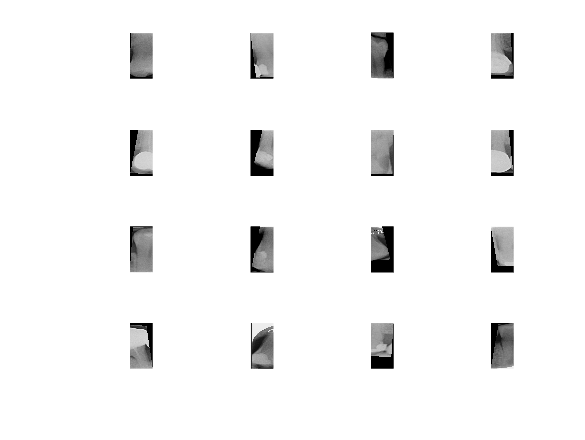

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## Load Pretrained Network

net = alexnet;

analyzeNetwork(net)

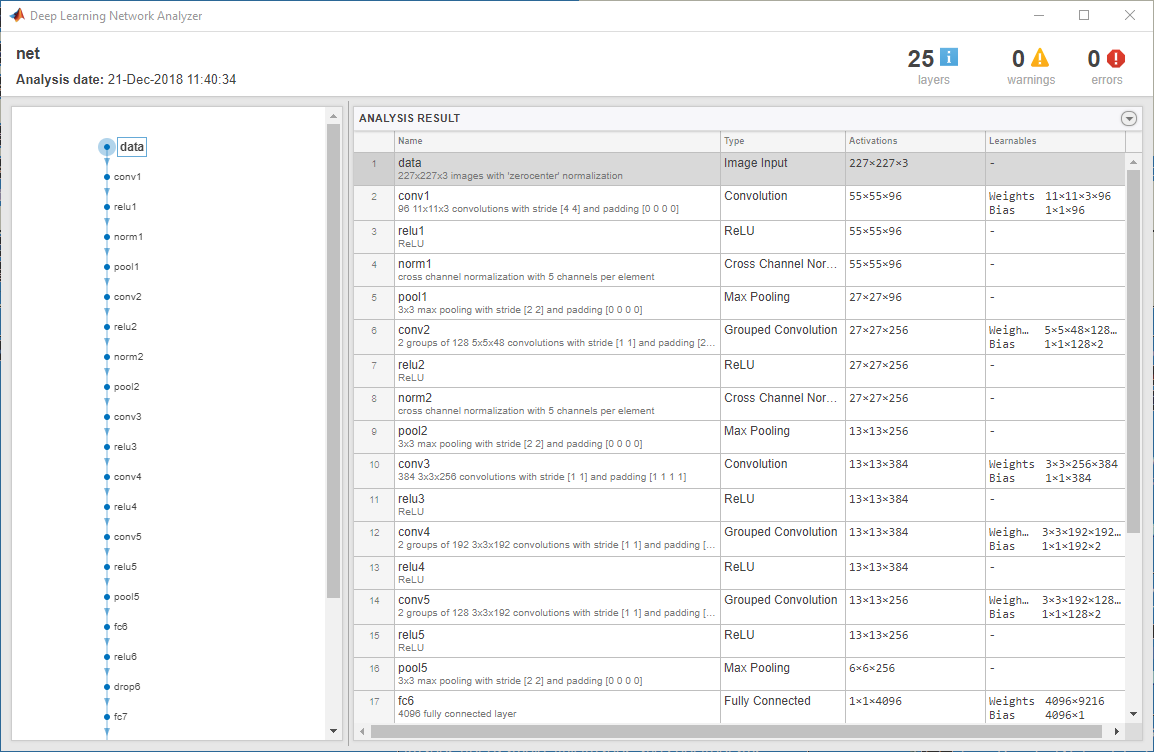

The first layer, the image input layer, requires input images of size 227-by-227-by-3, where 3 is the number of color c

inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


## Replace Final Layers

layersTransfer = net.Layers(1:end-3);

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 4


layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## Train Network

pixelRange = [-25 25];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandYReflection',true, ...
    'RandXScale',[0.9 1.1], ...
    'RandYScale',[0.9 1.1]);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

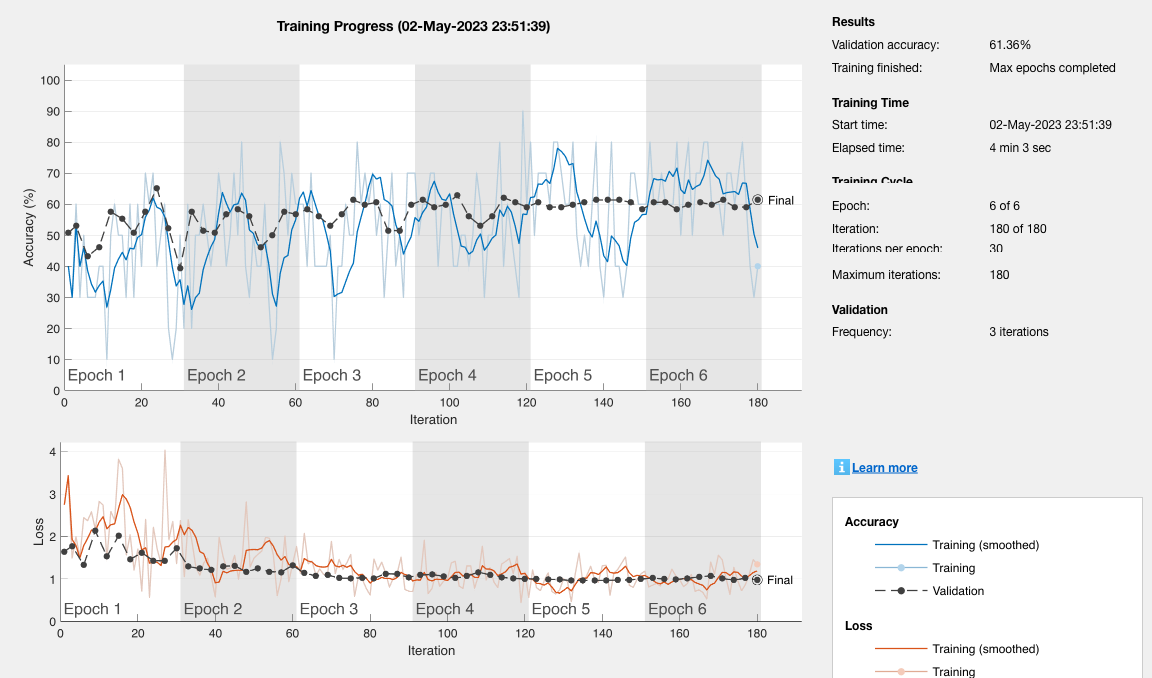

netTransfer = trainNetwork(augimdsTrain,layers,options);

## Classify Validation Images

Classify the validation images using the fine-tuned network.

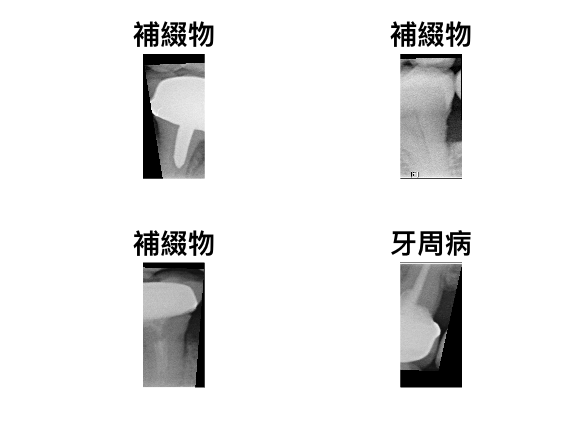

[YPred,scores] = classify(netTransfer,augimdsValidation);
idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.6136




A = 1

A = 1